# TUTORIAL 2: SHEAR FLOW AND SHEAR CENTER

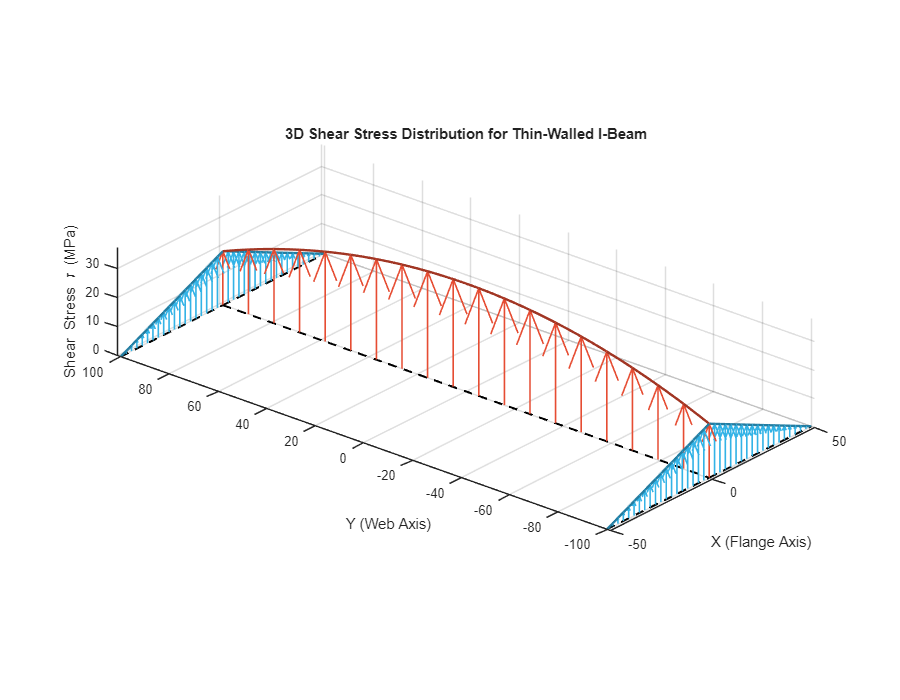

% =========================================================================
% MATLAB Script: 3D Thin-Walled Shear Stress Distribution (I-Beam)
% =========================================================================
clear; clc; close all;

% --- 1. Geometric & Material Properties ---
b = 100;        % Total flange width (mm)
h = 200;        % Total web height (mm)
tf = 5;         % Flange thickness (mm)
tw = 5;         % Web thickness (mm)
Vy = 50e3;      % Vertical shear force (N)

% Moment of Inertia (Ix) for thin-walled I-section
Ix = (tw * h^3)/12 + 2 * (b * tf * (h/2)^2);

% Setup 3D Figure
figure('Color', 'w', 'Position', [100 100 900 700]);
ax = axes; 
hold(ax, 'on');
grid(ax, 'on');
view(ax, -50, 25);
xlabel(ax, 'X (Flange Axis)');
ylabel(ax, 'Y (Web Axis)');
zlabel(ax, 'Shear Stress \tau (MPa)');
title(ax, '3D Shear Stress Distribution for Thin-Walled I-Beam');

% --- 2. Shear Stress Functions \tau(s) ---
% Top/Bottom Flange: \tau = (V_y * Q_f) / (I_x * t_f)
% s_f goes from 0 (outer edge) to b/2 (center web junction)
tau_flange = @(s_f) (Vy * (h/2) .* (b/2-s_f)) / Ix;

% Web: \tau = (V_y * Q_w) / (I_x * t_w)
% y_web goes from +h/2 (top) to -h/2 (bottom)
tau_web = @(y_web) (Vy / Ix) * ((b/2)*(h/2) + 0.5*((h/2)^2 - y_web.^2));


% --- 3. Plot 3D Thin Ribbons for Each Wall Segment ---

% Top Flange - Left Half (x: -b/2 to 0, y: +h/2)
plot_thin_ribbon(ax, -b/2, h/2, 0, h/2, @(s) tau_flange((1-s)*(b/2)), [0.2 0.7 0.9]);

% Top Flange - Right Half (x: 0 to b/2, y: +h/2)
plot_thin_ribbon(ax, 0, h/2, b/2, h/2, @(s) tau_flange(s*(b/2)), [0.2 0.7 0.9]);

% Bottom Flange - Left Half (x: -b/2 to 0, y: -h/2)
plot_thin_ribbon(ax, -b/2, -h/2, 0, -h/2, @(s) tau_flange((1-s)*(b/2)), [0.2 0.7 0.9]);

% Bottom Flange - Right Half (x: 0 to b/2, y: -h/2)
plot_thin_ribbon(ax, 0, -h/2, b/2, -h/2, @(s) tau_flange(s*(b/2)), [0.2 0.7 0.9]);

% Web (x: 0, y: +h/2 to -h/2)
plot_thin_ribbon(ax, 0, h/2, 0, -h/2, @(s) tau_web((1-s)*(h/2) - s*(h/2)), [0.9 0.3 0.2]);

% Adjust axes scaling & isometric proportions
axis(ax, 'equal');
rotate3d on;


% =========================================================================
% Helper Function: Builds 3D Vector/Quiver Plots along 1D Thin-Walled Paths
% =========================================================================
function plot_thin_ribbon(ax, x0, y0, x1, y1, tau_func, color_map)
    N_pts = 20; % Reduced point density so arrows don't overlap heavily
    s = linspace(0, 1, N_pts);
    tau_vals = tau_func(s);

    % Base coordinates on XY plane (Z = 0)
    X_base = x0 + s * (x1 - x0);
    Y_base = y0 + s * (y1 - y0);
    Z_base = zeros(size(s));

    % Vector components (pointing purely along Z with magnitude tau_vals)
    U = zeros(size(s)); % No X displacement
    V = zeros(size(s)); % No Y displacement
    W = tau_vals;       % Magnitude along Z

    % 1. Draw vector arrows from Z=0 up to Z=\tau
    % Setting scale factor (8th parameter) to 0 prevents automatic scaling
    quiver3(ax, X_base, Y_base, Z_base, U, V, W, 0, ...
            'Color', color_map, 'LineWidth', 1.2, 'MaxHeadSize', 0.4);

    % 2. Draw centerline profile on the XY plane (Z = 0)
    plot3(ax, X_base, Y_base, Z_base, 'k--', 'LineWidth', 1.5);

    % 3. Connect arrow tips with a smooth envelope curve (\tau distribution)
    s_dense = linspace(0, 1, 100);
    X_dense = x0 + s_dense * (x1 - x0);
    Y_dense = y0 + s_dense * (y1 - y0);
    tau_dense = tau_func(s_dense);

    plot3(ax, X_dense, Y_dense, tau_dense, 'Color', color_map*0.7, 'LineWidth', 1.8);
end



## PROBLEM 1:

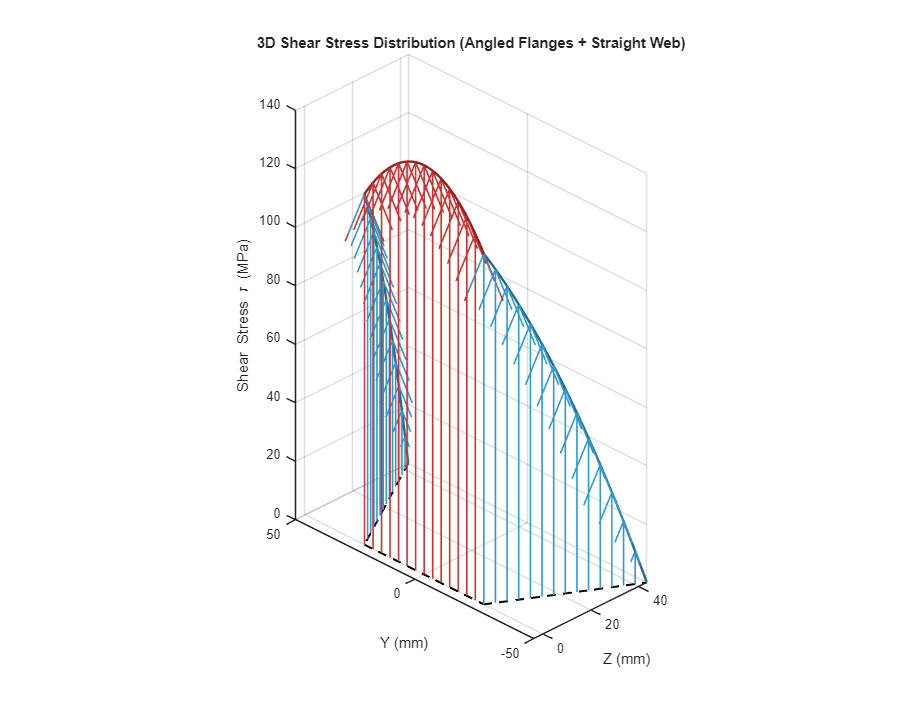

% =========================================================================
% MATLAB Script: 3D Vector Shear Stress Plot for Hexagonal/C-Channel
% =========================================================================
clear; clc; close all;

% --- 1. Geometry & Mechanics Setup ---
a = 50;           % Base length dimension (mm)
t = 2;            % Thickness (mm)
Vy = 20e3;        % Vertical Shear Load (N)

% Moment of Inertia (I_z) about neutral axis (y = 0)
I_web    = (t * a^3) / 12;
I_flange = (7/12) * t * a^3;
Iz       = I_web + 2 * I_flange;

% Canvas Setup
figure('Color', 'w', 'Position', [100 100 950 750]);
ax = axes; hold(ax, 'on'); grid(ax, 'on');
view(ax, -45, 30);
xlabel(ax, 'Z (mm)'); ylabel(ax, 'Y (mm)'); zlabel(ax, 'Shear Stress \tau (MPa)');
title(ax, '3D Shear Stress Distribution (Angled Flanges + Straight Web)');

% --- 2. Stress Equations ---

% Segment 1: Top Flange (s1 from 0 to a)
Q_flange = @(s1) t .* (a .* s1 - 0.25 .* (s1.^2));
tau_top_flange = @(s1) (Vy .* Q_flange(s1)) ./ (Iz * t);

% Segment 2: Web (s2 from 0 to a)
Q_web_start = Q_flange(a);
Q_web = @(s2) Q_web_start + t .* (0.5 * a .* s2 - 0.5 .* (s2.^2));
tau_web = @(s2) (Vy .* Q_web(s2)) ./ (Iz * t);

% Segment 3: Bottom Flange (Symmetric)
tau_bot_flange = @(s3) (Vy .* Q_flange(a - s3)) ./ (Iz * t);

% --- 3. Geometry Coordinates & Plotting ---
c_flange = [0.2 0.6 0.8];
c_web    = [0.8 0.2 0.2];

% Coordinates of Key Junctions
z_tip_top = a * cosd(30);   y_tip_top = a;
z_web_top = 0;               y_web_top = 0.5 * a;
z_web_bot = 0;               y_web_bot = -0.5 * a;
z_tip_bot = a * cosd(30);   y_tip_bot = -a;

% 1. Top Angled Flange
plot_vector_ribbon(ax, z_tip_top, y_tip_top, z_web_top, y_web_top, ...
                   @(s) tau_top_flange(s * a), c_flange);

% 2. Vertical Web
plot_vector_ribbon(ax, z_web_top, y_web_top, z_web_bot, y_web_bot, ...
                   @(s) tau_web(s * a), c_web);

% 3. Bottom Angled Flange
plot_vector_ribbon(ax, z_web_bot, y_web_bot, z_tip_bot, y_tip_bot, ...
                   @(s) tau_bot_flange(s * a), c_flange);

axis(ax, 'equal');
rotate3d on;


% =========================================================================
% Helper Function: Builds 3D Vector/Quiver Plots
% =========================================================================
function plot_vector_ribbon(ax, x0, y0, x1, y1, tau_func, color_map)
    N_pts = 15;
    s = linspace(0, 1, N_pts);
    tau_vals = tau_func(s);
    
    % Base coordinates on ZY plane
    X_base = x0 + s .* (x1 - x0);
    Y_base = y0 + s .* (y1 - y0);
    Z_base = zeros(size(s));
    
    % Stress magnitude along 3D Z-axis
    U = zeros(size(s));
    V = zeros(size(s));
    W = tau_vals;
    
    % 1. Quiver arrows
    quiver3(ax, X_base, Y_base, Z_base, U, V, W, 0, ...
            'Color', color_map, 'LineWidth', 1.2, 'MaxHeadSize', 0.35);
        
    % 2. Baseline profile
    plot3(ax, [x0 x1], [y0 y1], [0 0], 'k--', 'LineWidth', 1.5);
      
    % 3. Smooth envelope curve
    s_dense = linspace(0, 1, 100);
    X_dense = x0 + s_dense .* (x1 - x0);
    Y_dense = y0 + s_dense .* (y1 - y0);
    tau_dense = tau_func(s_dense);
    
    plot3(ax, X_dense, Y_dense, tau_dense, 'Color', color_map*0.7, 'LineWidth', 1.8);
end

## PROBLEM 2 :

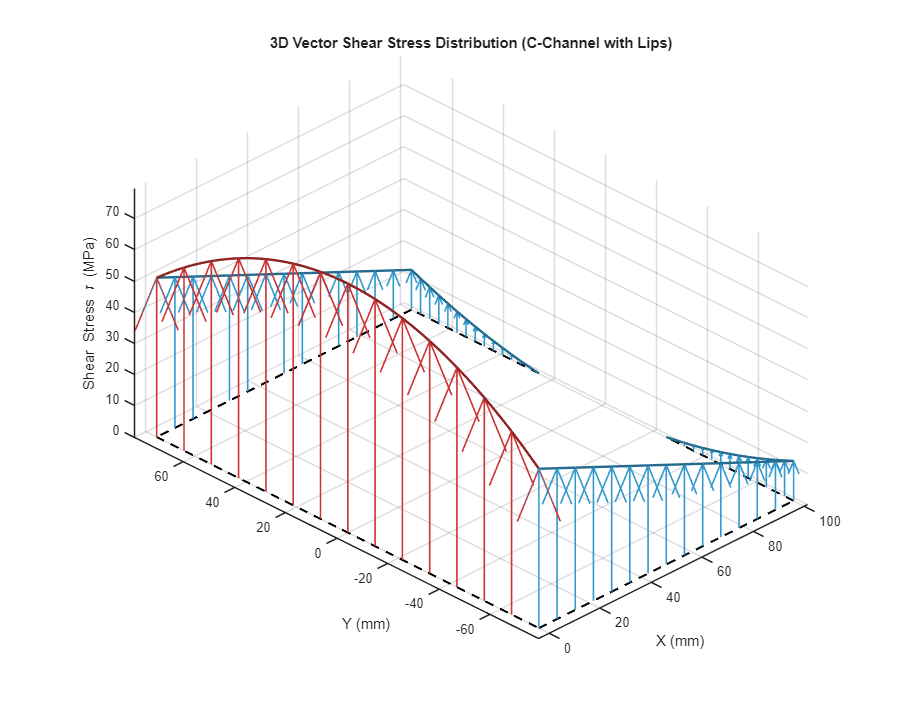

% =========================================================================
% MATLAB Script: Corrected 3D Vector Shear Stress Plot (C-Channel)
% =========================================================================
clear; clc; close all;

% --- 1. Geometry & Mechanics Setup ---
a = 50;           % Base length dimension (mm)
t = 2;            % Base thickness (mm)
Vy = 20e3;        % Vertical shear load (N)

% Moment of Inertia (I_x) about neutral axis (y = 0)
I_web     = ((2*t) * (3*a)^3) / 12;
I_flanges = 2 * ( (2*a * t^3)/12 + (2*a * t) * (1.5*a)^2 );
I_lips    = 2 * ( (t * a^3)/12   + (a * t)   * (1.0*a)^2 ); % Centroid at y = 1.0a

Ix = I_web + I_flanges + I_lips;

% Setup 3D Figure
figure('Color', 'w', 'Position', [100 100 950 750]);
ax = axes; hold(ax, 'on'); grid(ax, 'on');
view(ax, -45, 30);
xlabel(ax, 'X (mm)'); ylabel(ax, 'Y (mm)'); zlabel(ax, 'Shear Stress \tau (MPa)');
title(ax, '3D Vector Shear Stress Distribution (C-Channel with Lips)');

% --- 2. Corrected Q(s) & \tau(s) Equations ---

% Top Lip (s1: 0 to a)
Q_lip = @(s1) t .* (0.5*a .* s1 + 0.5 .* s1.^2); 
tau_lip = @(s1) (Vy .* Q_lip(s1)) ./ (Ix * t);

% Top Flange (s2: 0 to 2a)
Q_top_flange_start = Q_lip(a);
Q_top_flange = @(s2) Q_top_flange_start + (t .* s2 .* (1.5*a));
tau_top_flange = @(s2) (Vy .* Q_top_flange(s2)) ./ (Ix * t);

% Web (s3: 0 to 3a, Web thickness = 2t)
Q_web_start = Q_top_flange(2*a);
Q_web = @(s3) Q_web_start + (2*t) .* (1.5*a .* s3 - 0.5 .* s3.^2);
tau_web = @(s3) (Vy .* Q_web(s3)) ./ (Ix * (2*t));

% Bottom Flange & Lip (Symmetric)
tau_bot_flange = @(s4) (Vy .* Q_top_flange(2*a - s4)) ./ (Ix * t);
tau_bot_lip    = @(s5) (Vy .* Q_lip(a - s5)) ./ (Ix * t);

% --- 3. Plot Segments (Scaling s from [0,1] to actual segment lengths) ---
c_top = [0.2 0.6 0.8];
c_web = [0.8 0.2 0.2];

% 1. Top Lip (length = a)
plot_vector_ribbon(ax, 2*a, 0.5*a, 2*a, 1.5*a, @(s) tau_lip(s * a), c_top);

% 2. Top Flange (length = 2a)
plot_vector_ribbon(ax, 2*a, 1.5*a, 0, 1.5*a, @(s) tau_top_flange(s * 2*a), c_top);

% 3. Web (length = 3a)
plot_vector_ribbon(ax, 0, 1.5*a, 0, -1.5*a, @(s) 2*tau_web(s * 3*a), c_web);

% 4. Bottom Flange (length = 2a)
plot_vector_ribbon(ax, 0, -1.5*a, 2*a, -1.5*a, @(s) tau_bot_flange(s * 2*a), c_top);

% 5. Bottom Lip (length = a)
plot_vector_ribbon(ax, 2*a, -1.5*a, 2*a, -0.5*a, @(s) tau_bot_lip(s * a), c_top);

axis(ax, 'equal');
rotate3d on;


% % =========================================================================
% % Helper Function: Vector Arrow (Quiver) Renderer
% % =========================================================================
% function plot_vector_ribbon(ax, x0, y0, x1, y1, tau_func, color_map)
%     N_pts = 15;
%     s = linspace(0, 1, N_pts);
%     tau_vals = tau_func(s);
% 
%     X_base = x0 + s .* (x1 - x0);
%     Y_base = y0 + s .* (y1 - y0);
%     Z_base = zeros(size(s));
% 
%     U = zeros(size(s));
%     V = zeros(size(s));
%     W = tau_vals;
% 
%     % Draw Quiver Arrows
%     quiver3(ax, X_base, Y_base, Z_base, U, V, W, 0, ...
%             'Color', color_map, 'LineWidth', 1.2, 'MaxHeadSize', 0.35);
% 
%     % Draw Centerline
%     plot3(ax, [x0 x1], [y0 y1], [0 0], 'k--', 'LineWidth', 1.5);
% 
%     % Draw Smooth Envelope Curve
%     s_dense = linspace(0, 1, 100);
%     X_dense = x0 + s_dense .* (x1 - x0);
%     Y_dense = y0 + s_dense .* (y1 - y0);
%     tau_dense = tau_func(s_dense);
% 
%     plot3(ax, X_dense, Y_dense, tau_dense, 'Color', color_map*0.7, 'LineWidth', 1.8);
% end


## PROBLEM 3:

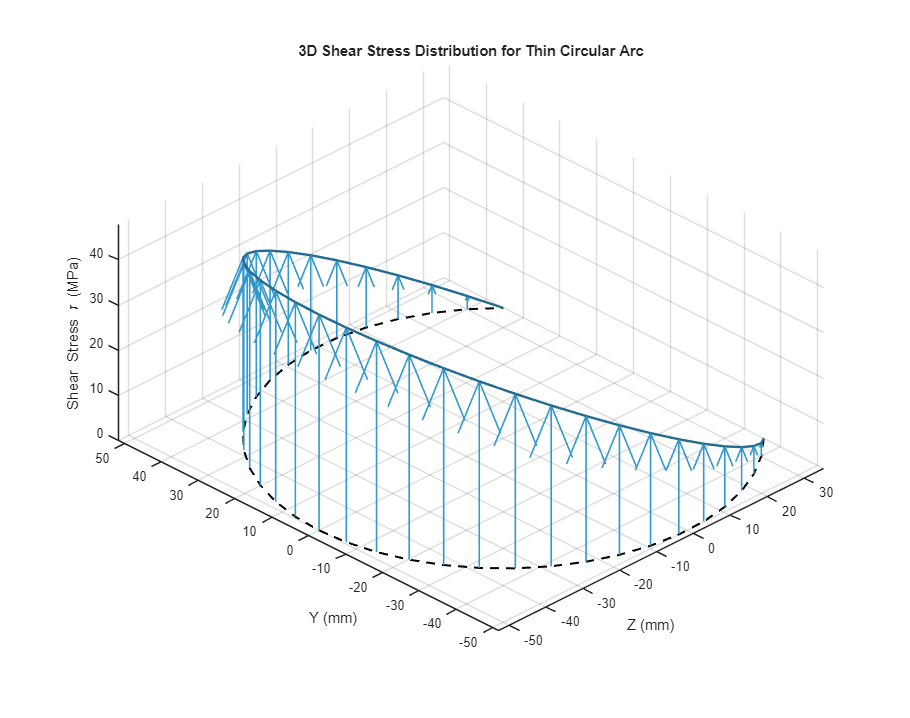

% =========================================================================
% MATLAB Script: 3D Vector Shear Stress Plot for Thin Circular Arc
% =========================================================================
clear; clc; close all;

% --- 1. Geometry & Mechanics Setup ---
R = 50;           % Radius of circular arc (mm)
t = 2;            % Uniform thickness (mm)
alpha_deg = 135;  % Half-angle in degrees (e.g., 135 deg for total arc of 270 deg)
Vy = -8e3;        % Vertical Shear Load (N)

alpha = deg2rad(alpha_deg); % Convert to radians

% Moment of Inertia (I_z) about horizontal neutral axis (y = 0)
Iz = R^3 * t * (alpha - sin(2*alpha)/2);

% Setup 3D Canvas
figure('Color', 'w', 'Position', [100 100 950 750]);
ax = axes; hold(ax, 'on'); grid(ax, 'on');
view(ax, -45, 30);
xlabel(ax, 'Z (mm)'); ylabel(ax, 'Y (mm)'); zlabel(ax, 'Shear Stress \tau (MPa)');
title(ax, '3D Shear Stress Distribution for Thin Circular Arc');

% --- 2. Stress Function ---
% Q(theta) = R^2 * t * (cos(alpha) - cos(theta))
Q_arc = @(th) R^2 * t .* (cos(alpha) - cos(th));
tau_arc = @(th) (Vy .* Q_arc(th)) ./ (Iz * t);

% --- 3. Compute Coordinates & Plot Vector Ribbon ---
N_pts = 35;
theta = linspace(-alpha, alpha, N_pts);

% Baseline parametric coordinates on ZY plane
% Note: Z axis points left in the diagram (Z = -R*cos(theta))
Z_base = -R * cos(theta);
Y_base =  R * sin(theta);
X_base = zeros(size(theta));

% Compute shear stress magnitudes
Tau_vals = tau_arc(theta);

% Plot the vector ribbon along the arc
c_arc = [0.2 0.6 0.8];
plot_circular_ribbon(ax, Z_base, Y_base, X_base, Tau_vals, c_arc);

axis(ax, 'equal');
rotate3d on;


% =========================================================================
% Helper Function: Circular Path Vector Renderer
% =========================================================================
function plot_circular_ribbon(ax, Z_base, Y_base, X_base, Tau_vals, color_map)
    % Quiver displacement vectors pointing vertically along stress axis (W)
    U = zeros(size(Tau_vals));
    V = zeros(size(Tau_vals));
    W = Tau_vals;
    
    % 1. Vector Quiver Arrows
    quiver3(ax, Z_base, Y_base, X_base, U, V, W, 0, ...
            'Color', color_map, 'LineWidth', 1.2, 'MaxHeadSize', 0.35);
        
    % 2. Baseline Arc Profile (Stress = 0 plane)
    plot3(ax, Z_base, Y_base, X_base, 'k--', 'LineWidth', 1.5);
      
    % 3. Smooth Envelope Curve connecting stress peaks
    plot3(ax, Z_base, Y_base, Tau_vals, 'Color', color_map*0.7, 'LineWidth', 1.8);
end

## PROBLEM 4:

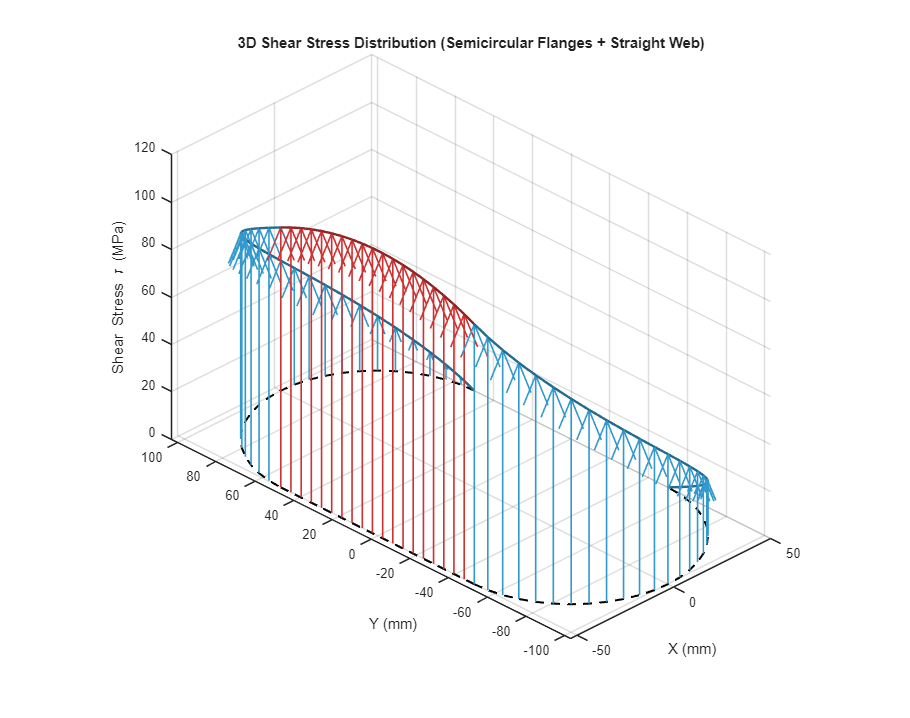

% =========================================================================
% MATLAB Script: 3D Shear Stress for Channel with Semicircular Flanges
% =========================================================================
clear; clc; close all;

% --- 1. Geometry & Mechanics Parameters ---
a = 50;           % Mean radius / half-web height (mm)
t = 2;            % Thin wall thickness (mm)
Vy = 20e3;        % Vertical shear load (N)

% Moment of Inertia (I_x) about Neutral Axis (y = 0)
I_web = (t * (2*a)^3) / 12;
I_flanges = 2 * (t * a^3 * (1.5*pi + 4) / 2); % Both top & bottom semicircles
Ix = I_web + I_flanges;

% Setup 3D Canvas
figure('Color', 'w', 'Position', [100 100 950 750]);
ax = axes; hold(ax, 'on'); grid(ax, 'on');
view(ax, -45, 30);
xlabel(ax, 'X (mm)'); ylabel(ax, 'Y (mm)'); zlabel(ax, 'Shear Stress \tau (MPa)');
title(ax, '3D Shear Stress Distribution (Semicircular Flanges + Straight Web)');

% --- 2. Functional Definitions for Shear Stress \tau ---

% 1. Top Semicircle: theta in [0, pi] (from right free-edge x=0, y=a to web top x=-a, y=a)
Q_top = @(th) t * a^2 .* (th + 1 - cos(th));
tau_top = @(th) (Vy .* Q_top(th)) ./ (Ix * t);

% 2. Vertical Web: y_val from +a down to -a
Q_top_end = Q_top(pi); % Continuity from top flange
Q_web = @(y_val) Q_top_end + 0.5 * t .* (a^2 - y_val.^2);
tau_web = @(y_val) (Vy .* Q_web(y_val)) ./ (Ix * t);

% 3. Bottom Semicircle: theta in [0, pi] (Symmetric return)
tau_bot = @(th) (Vy .* Q_top(pi - th)) ./ (Ix * t);

% --- 3. Compute Coordinates & Plot Vector Ribbons ---
c_curve = [0.2 0.6 0.8];
c_web   = [0.8 0.2 0.2];

% A. TOP SEMICIRCLE
N_top = 25;
th_top = linspace(0, pi, N_top);
X_top = a * cos(th_top);
Y_top = a + a * sin(th_top);
Z_top = zeros(size(th_top));
Tau_top_vals = tau_top(th_top);

plot_ribbon(ax, X_top, Y_top, Z_top, Tau_top_vals, c_curve);

% B. VERTICAL STRAIGHT WEB
N_web = 20;
Y_web = linspace(a, -a, N_web);
X_web = -a * ones(size(Y_web));
Z_web = zeros(size(Y_web));
Tau_web_vals = tau_web(Y_web);

plot_ribbon(ax, X_web, Y_web, Z_web, Tau_web_vals, c_web);

% C. BOTTOM SEMICIRCLE
th_bot = linspace(0, pi, N_top);
X_bot = -a * cos(th_bot);
Y_bot = -a - a * sin(th_bot);
Z_bot = zeros(size(th_bot));
Tau_bot_vals = tau_bot(th_bot);

plot_ribbon(ax, X_bot, Y_bot, Z_bot, Tau_bot_vals, c_curve);

axis(ax, 'equal');
rotate3d on;


% =========================================================================
% Helper Function: General Path Vector Renderer
% =========================================================================
function plot_ribbon(ax, X_base, Y_base, Z_base, Tau_vals, color_map)
    % Quiver arrows
    U = zeros(size(Tau_vals));
    V = zeros(size(Tau_vals));
    W = Tau_vals;
    
    quiver3(ax, X_base, Y_base, Z_base, U, V, W, 0, ...
            'Color', color_map, 'LineWidth', 1.2, 'MaxHeadSize', 0.35);
        
    % Base profile centerline
    plot3(ax, X_base, Y_base, Z_base, 'k--', 'LineWidth', 1.5);
      
    % Envelope curve connecting stress peaks
    plot3(ax, X_base, Y_base, Tau_vals, 'Color', color_map*0.7, 'LineWidth', 1.8);
end